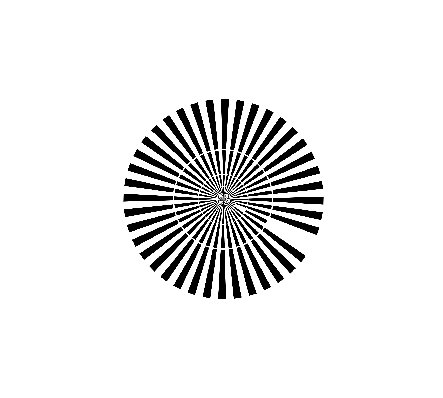

% Unidades
nm = 1E-9;
um = 1E-6;
mm = 1E-3;

M = 10;

% Tamaño de la representación
Nx = 2048;
Ny = Nx;

% Condiciones de muestreo
dx = 6.513*mm/(Nx*M); 
dy = dx;

% Longitud de Onda de iluminación
lambda = 720*nm;

% Apertura númerica
AN = 0.25;

estrella = imread('SiemensStar_2048_AD.png');
%estrella = imresize(estrella,Nx/780);
estrella = rgb2gray(estrella);
imshow(estrella)
colormap("gray")


%La imagen pasará por un primer lente, el cual es un 
% objetivo 10x, en su distancia focal, lo cual representa 
% una transformada de Fourier.

f2 = 200*mm;


%Microscopio de un foton 

[salidaPura, observacion, pupila] = microscopio(estrella,M,f2,AN, Nx, Ny, dx, dy, lambda);

rpupila = 226.1458

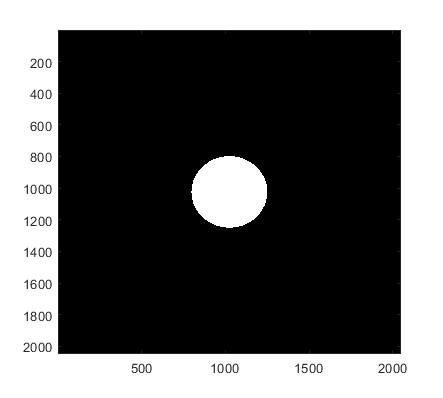

observacion = imrotate(observacion,180);
imagesc(pupila)

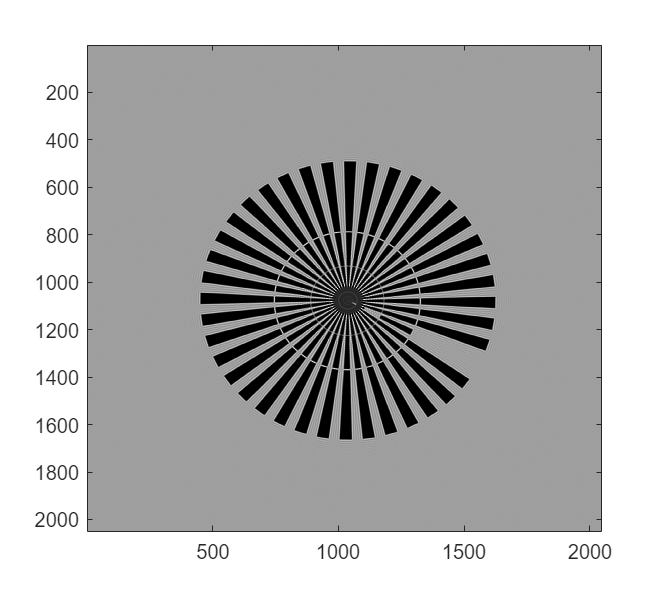

imagesc(observacion)


%Microscopio de dos fotones 